# Compare Separation and Experiment Tube Test Data - anti-Events 

#### Exp - continuous event mining 

% Remove contamination and transform data 
load('exp_tube_con_anti.mat')
anti=rem_dup_em(anti,'nround',1);
[N,nm]=size(anti{1,1}.eve);

Find events with 4 specified lengths: 5s, 20s, 40s, 100s 

klist={5,20,40,100};% find events separately for each k
ev_merge=cell(N,nm);
% events
for p=1:N
    for m=1:nm
        [allt{p,m},allm{p,m},allk{p,m}]=alltmk(klist,anti{1,1}.K{p,m},anti{1,1}.M{p,m},anti{1,1}.time{p,m});
        ev_merge{p,m}=cell(1,4);
        for k=1:4
            ev_merge{p,m}{k}=allt{p,m}{k}+klist{k}/2;
            ev_merge{p,m}{k}=remove_time_ovp(ev_merge{p,m}{k},klist{k}); % remove highly overlapped events
        end
    end
end
anti{1,1}.ev_merge=ev_merge;

#### Same for separation data -

% Remove contamination and transform data 
load('sep_tube_con_anti.mat')
anti_sep=rem_dup_em(anti_sep,'nround',1);
[N,nm]=size(anti_sep{1,1}.eve);

Find events with 4 specified lengths: 5s, 20s, 40s, 100s 

klist={5,20,40,100};% find events separately for each k
ev_merge_sep=cell(N,nm);
% events
for p=1:N
    for m=1:nm
        [allt{p,m},allm{p,m},allk{p,m}]=alltmk(klist,anti_sep{1,1}.K{p,m},anti_sep{1,1}.M{p,m},anti_sep{1,1}.time{p,m});
        ev_merge_sep{p,m}=cell(1,4);
        for k=1:4
            ev_merge_sep{p,m}{k}=allt{p,m}{k}+klist{k}/2;
            ev_merge_sep{p,m}{k}=remove_time_ovp(ev_merge_sep{p,m}{k},klist{k}); % remove highly overlapped events
        end
    end
end
anti_sep{1,1}.ev_merge=ev_merge_sep;

Plot experiment data 

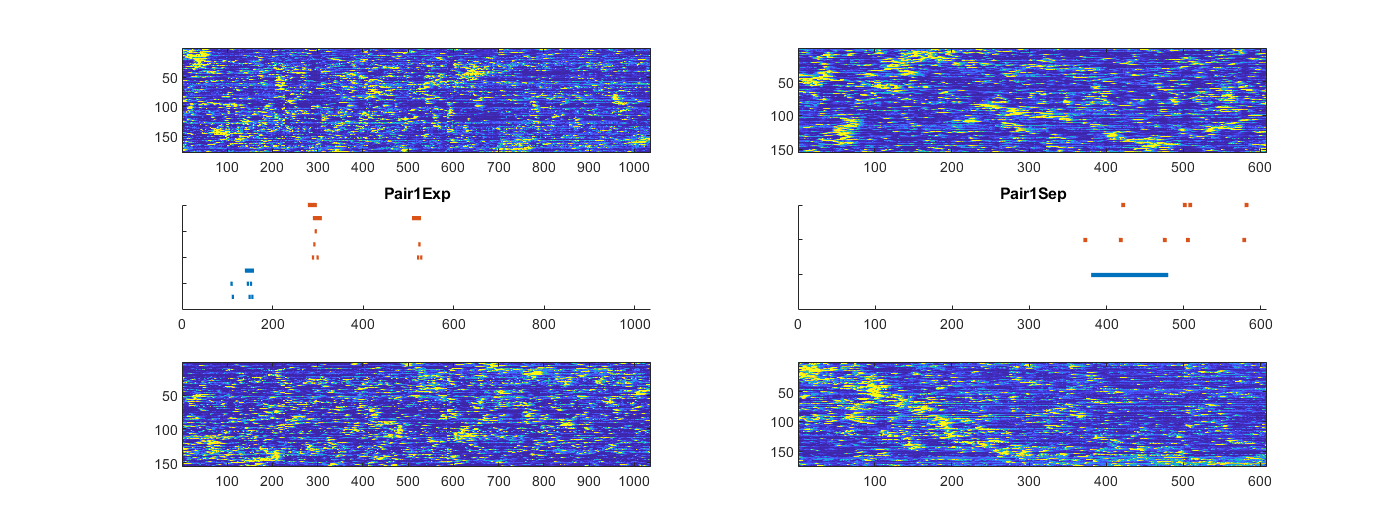

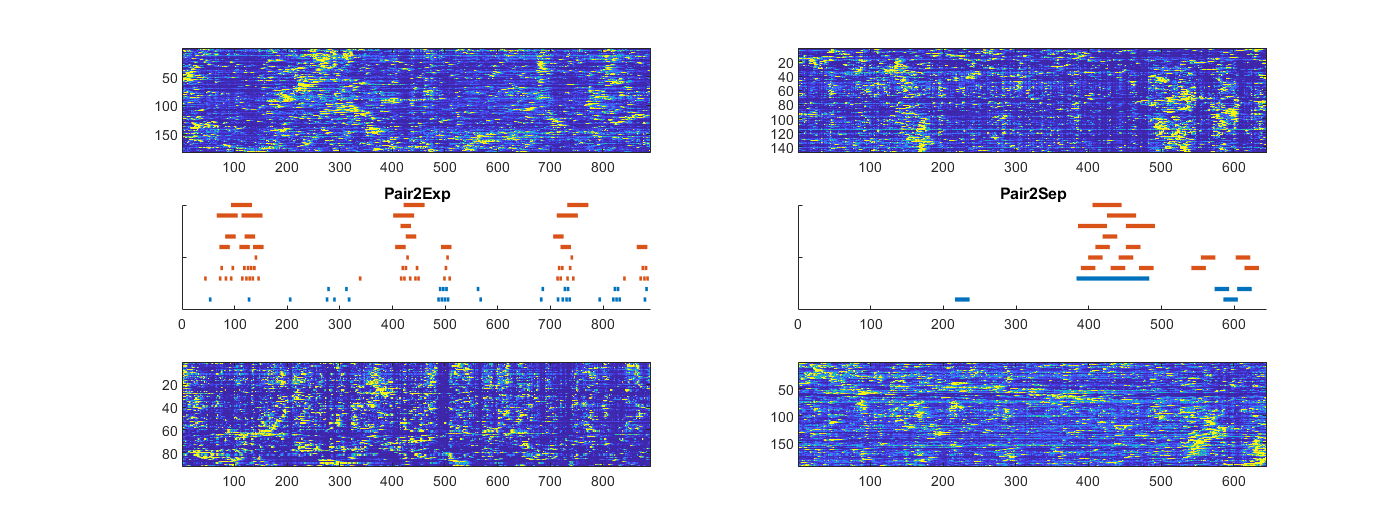

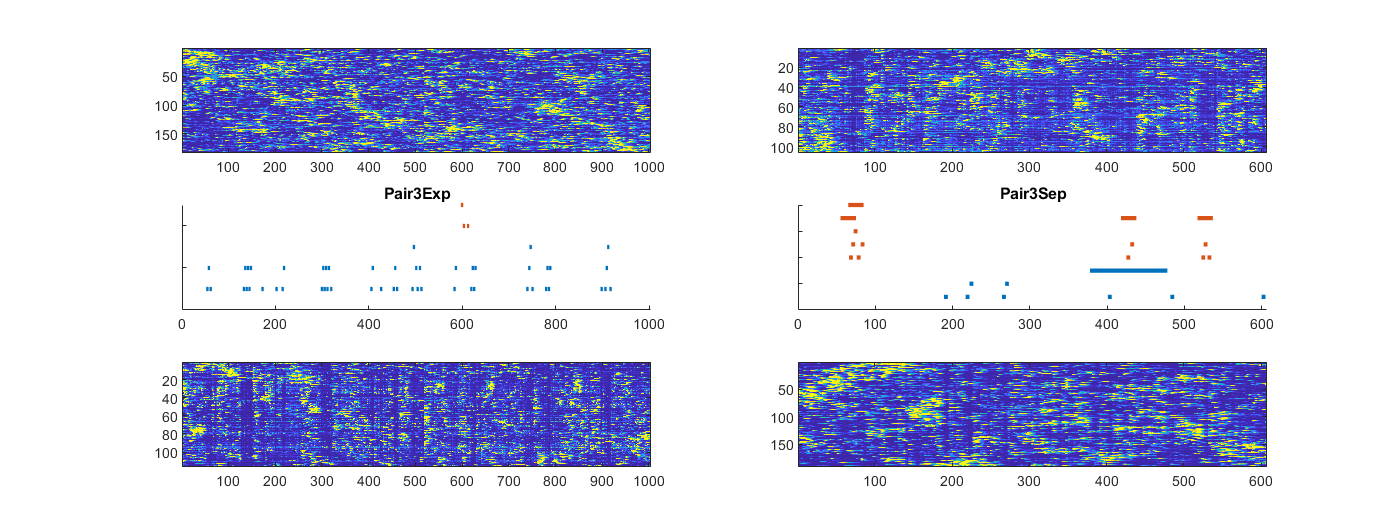

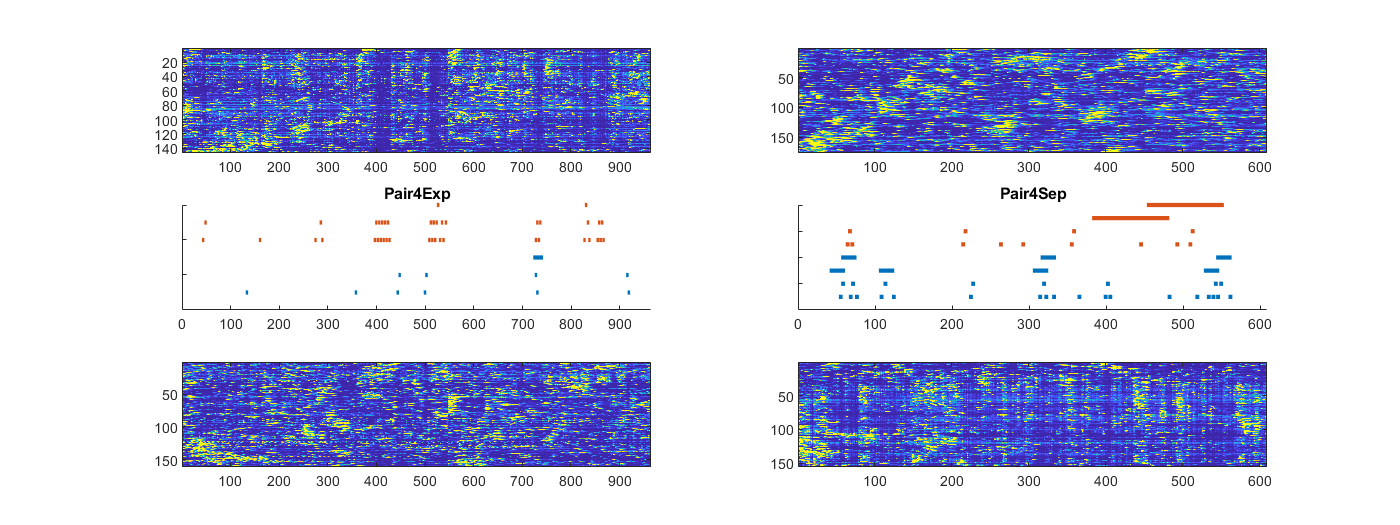

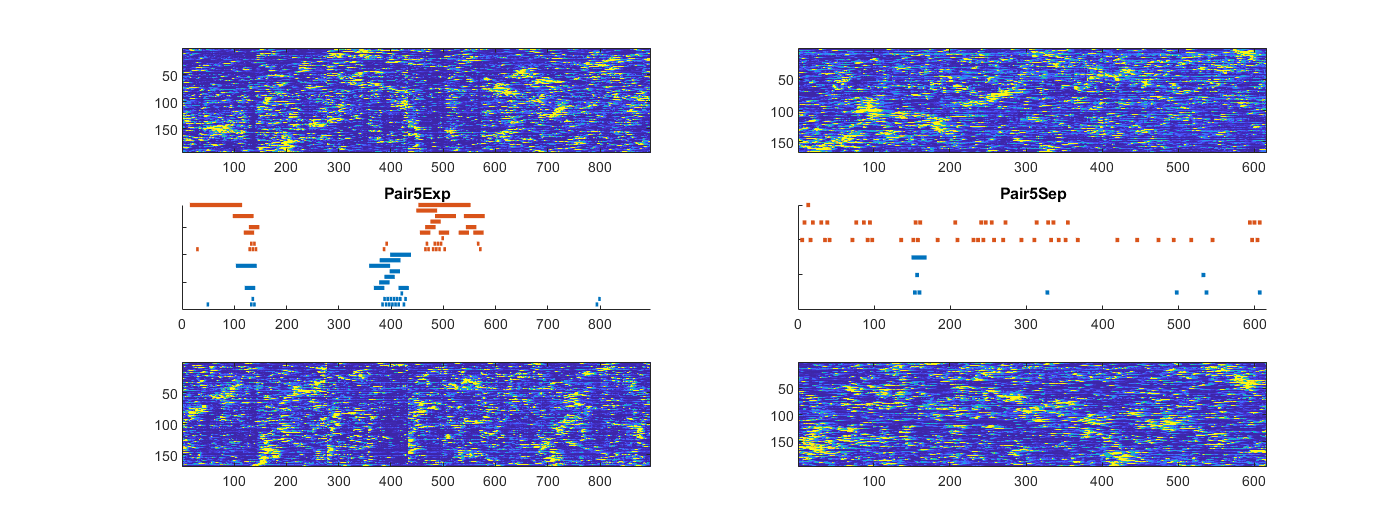

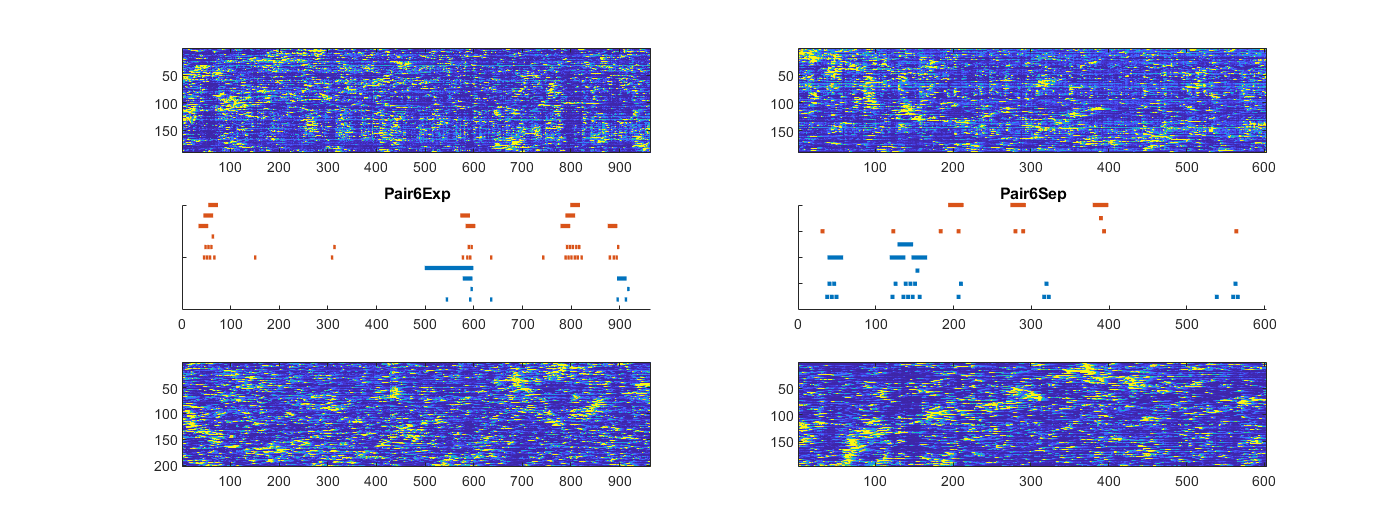

for p=1:N
f=figure;
f.Position(3)=2*f.Position(3);
subplot(3,2,1)
plot_raster(anti{1,1}.ca_cl{p,2},'bin',false);
subplot(3,2,3)
new_eve_plot_arena(ev_merge{p,1},ev_merge{p,2},klist,size(anti{1,1}.ca_cl{p,1},2));
title(sprintf('Pair%dExp',p))
subplot(3,2,5)
plot_raster(anti{1,1}.ca_cl{p,1},"bin",false);
subplot(3,2,2)
plot_raster(anti_sep{1,1}.ca_cl{p,2},'bin',false);
subplot(3,2,4)
new_eve_plot_arena(ev_merge_sep{p,1},ev_merge_sep{p,2},klist,size(anti_sep{1,1}.ca_cl{p,1},2));
title(sprintf('Pair%dSep',p))
subplot(3,2,6)
plot_raster(anti_sep{1,1}.ca_cl{p,1},"bin",false);
end

#### Compare number of events of the first 600s

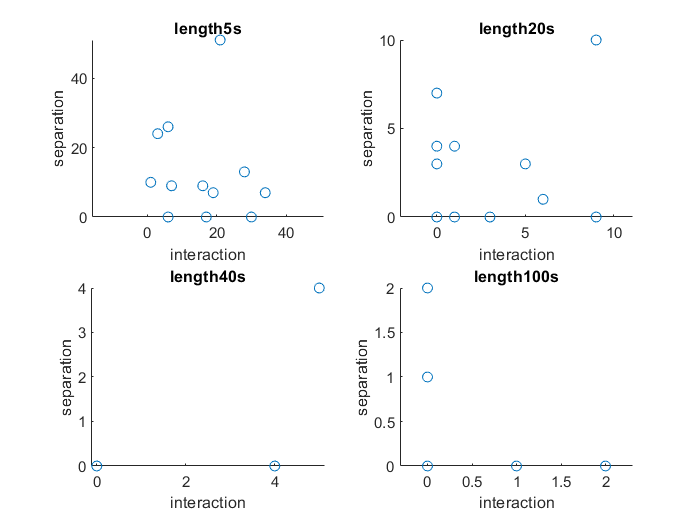

close all
n=0;l=600;
for p=1:N
    for m=1:2
        n=n+1;
        for k=1:4
            neve(k,1,n)=sum(ev_merge{p,m}{k}<l);
            neve(k,2,n)=sum(ev_merge_sep{p,m}{k}<l);
        end
    end
end
% err1=nanste(neve,3);
% hBar=bar(squeeze(mean(neve,3)));
% for k1 = 1:size(neve,2)
%     x(:,k1) = bsxfun(@plus, hBar(1).XData, hBar(k1).XOffset');    % Note: eXOffsete Is An Undocumented Feature; This Selects The xbarp Centres
%     y(:,k1) = hBar(k1).YData;                                     % Individual Bar Heights
% end
% hold on
% errorbar(x,y, err1, '.k')                                      % Plot Error Bars
% hold off
% legend(hBar,{'exp','sep'});xticklabels({'5s','20s','40s','100s'})
for k=1:4
    subplot(2,2,k)
    scatter(squeeze(neve(k,1,:)),squeeze(neve(k,2,:))); axis equal
    title(sprintf('length%ds',klist{k}));xlabel('interaction');ylabel('separation')
end